# Ejercicio 7.5

**Jose Antonio Lorencio Abril**

**a)** Las ecuaciones serán:


$$x'(t) = -\alpha\cdot x(t) - a\cdot y(t) + P(t)$$



$$y'(t) = -\beta\cdot y(t) - b\cdot x(t) + Q(t)$$


**b)** Primero introducimos los datos:

dia = 0:30;
efect = [66454, 65546, 64674, 63170, 62687, 61702, 60966, 59845, 59641, 59377, 59075, 58492, 57555, 56937, 56357, 55604, 55092, 54694, 54234, 53645, 53377, 53100, 53031, 52904, 52803, 52708, 52600, 52451, 52451, 52451, 52436];
a = 0.056;
b = 0.0106;

Y definimos las ecuaciones, teniendo en cuenta que $\alpha=\beta=P(t)=Q(t)=0$:

syms x(t);
syms y(t);
dx = diff(x,1);
dy = diff(y,1);

ode1 = dx == -a*y

$$ode1(t) = \frac{\partial }{\partial t}x\left(t\right)=-\frac{7\,y\left(t\right)}{125}$$

ode2 = dy == -b*x

$$ode2(t) = \frac{\partial }{\partial t}y\left(t\right)=-\frac{53\,x\left(t\right)}{5000}$$

odes = [ode1, ode2]

$$odes(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}x\left(t\right)=-\frac{7\,y\left(t\right)}{125} & \frac{\partial }{\partial t}y\left(t\right)=-\frac{53\,x\left(t\right)}{5000} \end{array}\right)$$


[xSol, ySol] = dsolve(odes, [x(0)==66454, y(0)==18000])

$$xSol = \frac{2\,\sqrt{3710}\,{\mathrm{e}}^{-\frac{\sqrt{3710}\,t}{2500}}\,\left(\frac{33227\,\sqrt{3710}}{140}+9000\right)}{53}-\frac{{\mathrm{e}}^{\frac{\sqrt{3710}\,t}{2500}}\,\left(18000\,\sqrt{3710}-1761031\right)}{53}$$

$$ySol = {\mathrm{e}}^{-\frac{\sqrt{3710}\,t}{2500}}\,\left(\frac{33227\,\sqrt{3710}}{140}+9000\right)+\frac{\sqrt{3710}\,{\mathrm{e}}^{\frac{\sqrt{3710}\,t}{2500}}\,\left(18000\,\sqrt{3710}-1761031\right)}{7420}$$

Y pasamos a compararlo con los datos reales:

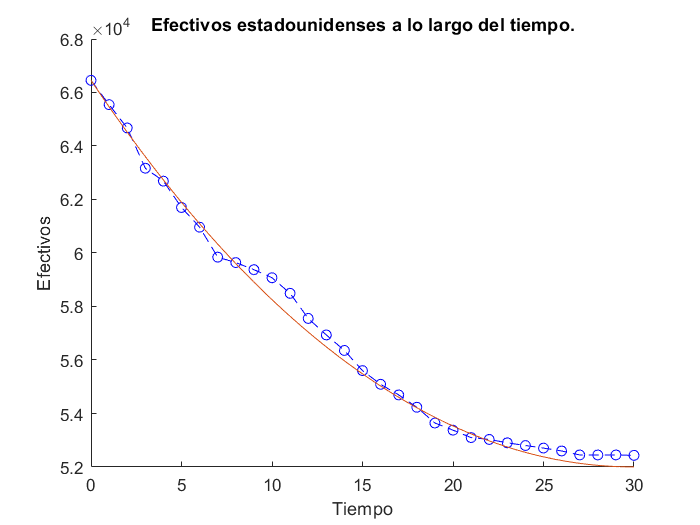

mes = 0:3000;
mes = mes / 100;

func = matlabFunction(xSol);
X = @(t) func(t);
xMes = X(mes);

figure(1)
hold on
plot(dia, efect, 'o--b')
plot(mes, xMes, '-')
title('Efectivos estadounidenses a lo largo del tiempo.')
xlabel('Tiempo')
ylabel('Efectivos')
hold off

**c)** Vamos primero a ver la evolución a largo plazo que proporcionan las soluciones de ambos bandos:

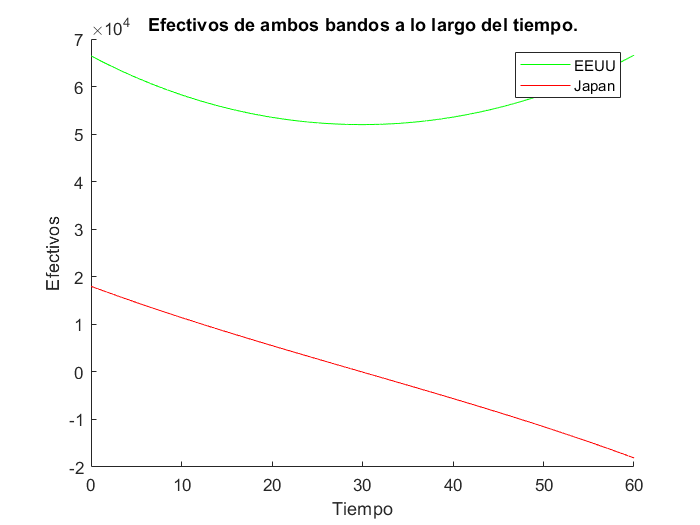

func2 = matlabFunction(ySol);
Y = @(t) func2(t);
ti = 0:6000;
ti = ti / 100;

xt = X(ti);
yt = Y(ti);


figure(2)
hold on
plot(ti, xt, 'g-')
plot(ti, yt, 'r-')
legend("EEUU", "Japan")
title('Efectivos de ambos bandos a lo largo del tiempo.')
xlabel('Tiempo')
ylabel('Efectivos')
hold off

Como vemos, cuando el ejército japonés llega a 0, el de EEUU comienza a subir. Esto no tiene sentido real, pero se entiende que cuando uno llega a 0, el otro gana el conflicto.

Debemos entonces encontrar un $Y_0$ de tal forma que el ejército estadounidense llegue a 0 antes.

Para esto, vamos a volver a resolver la edo, pero dejando libre la condición inicial $y_0$.

[xSol2, ySol2] = dsolve(odes, x(0)==66454)

$$xSol2 = \frac{2\,{\mathrm{e}}^{-\frac{\sqrt{3710}\,t}{2500}}\,\left(\sqrt{3710}\,C_{1}+1761031\right)}{53}-\frac{2\,\sqrt{3710}\,C_{1}\,{\mathrm{e}}^{\frac{\sqrt{3710}\,t}{2500}}}{53}$$

$$ySol2 = C_{1}\,{\mathrm{e}}^{\frac{\sqrt{3710}\,t}{2500}}+\frac{\sqrt{3710}\,{\mathrm{e}}^{-\frac{\sqrt{3710}\,t}{2500}}\,\left(\sqrt{3710}\,C_{1}+1761031\right)}{3710}$$

func3 = matlabFunction(xSol2);
X2 = @(t, C) func3(C, t);

func4 = matlabFunction(ySol2);
Y2 = @(t, C) func4(C, t);

syms T
syms c

[~, cc] = vpasolve(X2(T,c)==0, [T,c])

$$cc = 18.314040402769173782181470137963$$

  Es decir, que si tomamos una condición inicial $Y_0$ tal que $C_1=cc$, Japón ganaría la batalla en 151 días.

Como $Y2(0,C_1)=C_1+\frac{3710\cdot C_1 + \sqrt(3710)\cdot1761031}{3710}$, entonces, para resolver esto, hacemos:

syms Y0

vpasolve(Y2(0,cc)==Y0, Y0)

$$ans = 28948.755303280390838983769411992$$

Es decir, que si Japón hubiese empezado con 28949 soldados, hubiese ganado el conflicto. No obstante, puede que este no sea el valor más bajo para el que se verifica esto. Podemos intentar ahora darle un valor tentativo inicial que haga que la solución cambie, y con suerte sea menor. Como queremos que y0 sea lo menor posible, nos interesa obtener un $c_0$ lo menor posible también.

syms T
syms c

[tt, cc] = vpasolve(X2(T,c)==0, [T,c], [500, 0])

$$tt = 500.00000000000001401798745462449$$

$$cc = 0.00000075852405908781197305055724422163$$

Haciendo varias pruebas he observado que puedo disminuir $cc$ tanto como quiera, a costa de que el tiempo de victoria aumenta. Por tanto, parece razonable pensar que podemos tomar $C_0=0$ y que Japón gana la batalla en el límite.

syms Y0

y0 = vpasolve(Y2(0,0)==Y0, Y0)

$$y0 = 28912.127222474849986610934138298$$

Obteniendo que si Japón comienza con 28913 efectivos, ganará la guerra en algún momento.

Por último, comprobemos que los modelos realmente pronostican esto (gráficamente).

[xSol3, ySol3] = dsolve(odes, [x(0)==66454, y(0)==28913])

$$xSol3 = \frac{2\,\sqrt{3710}\,{\mathrm{e}}^{-\frac{\sqrt{3710}\,t}{2500}}\,\left(\frac{33227\,\sqrt{3710}}{140}+\frac{28913}{2}\right)}{53}-\frac{{\mathrm{e}}^{\frac{\sqrt{3710}\,t}{2500}}\,\left(28913\,\sqrt{3710}-1761031\right)}{53}$$

$$ySol3 = {\mathrm{e}}^{-\frac{\sqrt{3710}\,t}{2500}}\,\left(\frac{33227\,\sqrt{3710}}{140}+\frac{28913}{2}\right)+\frac{\sqrt{3710}\,{\mathrm{e}}^{\frac{\sqrt{3710}\,t}{2500}}\,\left(28913\,\sqrt{3710}-1761031\right)}{7420}$$


func5 = matlabFunction(xSol3)

func5 = function_handle with value:
    @(t)exp((6.090976933136424e+1.*t)./2.5e+3).*(6.090976933136424e+1.*2.8913e+4-1.761031e+6).*(-1.0./5.3e+1)+6.090976933136424e+1.*exp(6.090976933136424e+1.*t.*(-4.0e-4)).*(6.090976933136424e+1.*2.373357142857143e+2+1.44565e+4).*(2.0./5.3e+1)


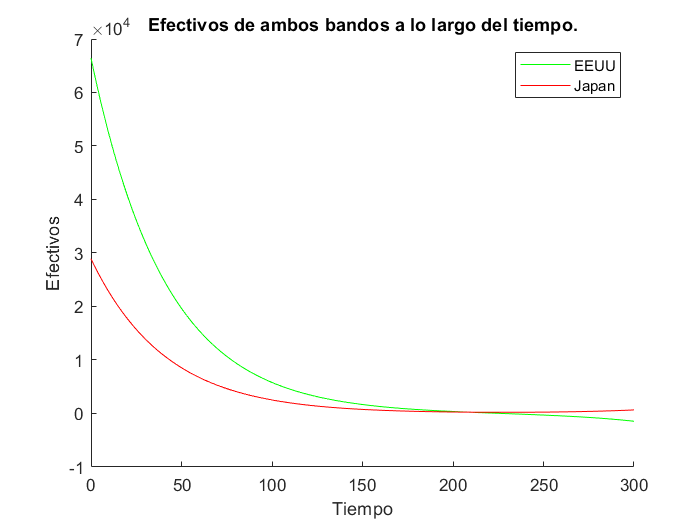

func6 = matlabFunction(ySol3);

X3 = @(t) func5(t);
Y3 = @(t) func6(t);

ti = 0:300000;
ti = ti / 1000;

xt = X3(ti);
yt = Y3(ti);


figure(3)
hold on
plot(ti, xt, 'g-')
plot(ti, yt, 'r-')
legend("EEUU", "Japan")
title('Efectivos de ambos bandos a lo largo del tiempo.')
xlabel('Tiempo')
ylabel('Efectivos')
hold off

Vamos a acercarnos un poco a ver cuántos japoneses sobreviven y vuelven a casa a celebrar:

syms TJ

tj = solve(X3(TJ)==0, TJ);

N = vpa(Y3(tj(2)))

$$N = 224.65188943905272011179964520133$$

Y sobreviven unos 225 soldados.